point_num = 50

point_num = 50

for_n = 10000

for_n = 10000


err = zeros(1,4)

err =      0     0     0     0


err_R = zeros(point_num,1)

err_R =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


err_T = zeros(point_num,1)

err_T =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


cnt = 1

cnt = 1


for j = 1:for_n
    a = rand(1)*10;
    b = rand(1)*10;
    c = rand(1)*10;
    d = rand(1)*10;
    % ax + by + cz + d = 0
    
    points = randn(point_num,3);
    
    for i = 1:point_num
        x = points(i,1);
        y = points(i,2);
        points(i,3) = (-d-a*x-b*y)/c;
    end
    %real points
    
    %random R
    [R,T] = randomRT();
    points_measure = points;
    for i = 1: point_num
        points_measure(i,:) = R*points(i,:)' + T + randn(3,1)*0.1;
    end
    %scatter3(points(:,1),points(:,2),points(:,3),'*')
    %scatter3(points_measure(:,1),points_measure(:,2),points_measure(:,3),'*')
    
    

    [diff_R,diff_T,det_R] = cal(point_num,points,points_measure,R,T);
    

    if diff_R>90
        diff_R = diff_R - 90;
    end
    if det_R == 1
        err_R(cnt,1) = diff_R;
        err_T(cnt,1) = diff_T;
        cnt = cnt + 1;
    end

end

disp(['finish ' num2str(cnt) ' in ' num2str(for_n)]);

finish 2405 in 10000


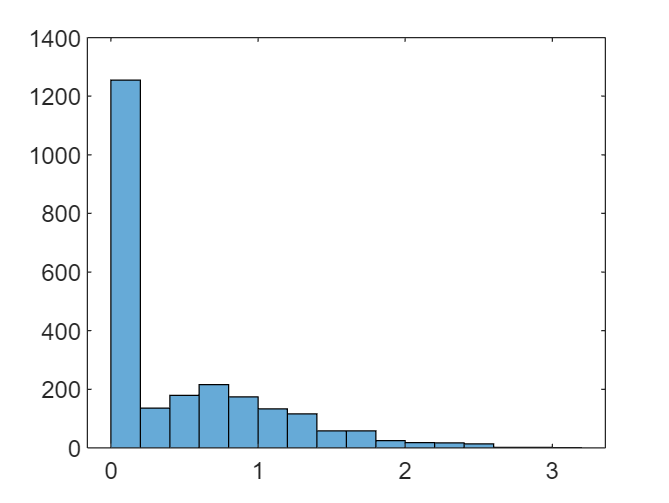

histogram(err_R)

disp(num2str(sum(err_R)/cnt))

0.45974


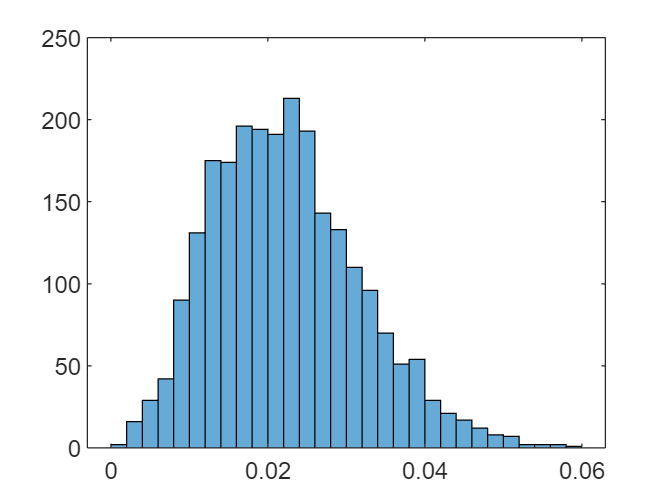


histogram(err_T)

disp(num2str(sum(err_T)/cnt))

0.022298
